% im = imread("");
im = [1, 4, 5, 11, 13, 2, 4, 5]

im =      1     4     5    11    13     2     4     5



imB = zeros(1, length(im)+2);

for i = 1:length(im)
    imB(i+1) = im(i);
end

imB(1) = imB(2);
imB(length(imB)) = imB(length(imB)-1);

imB

imB =      1     1     4     5    11    13     2     4     5     5


differ = zeros(1, length(im)+1);

for i = 1:length(im)+1
    differ(i) = abs(imB(i+1) - imB(i));
end

differ

differ =      0     3     1     6     2    11     2     1     0


differB = zeros(1, length(im));

for i = 1:length(im)
    differB(i) = differ(i+1) + differ(i);
end

differB

differB =      3     4     7     8    13    13     3     1


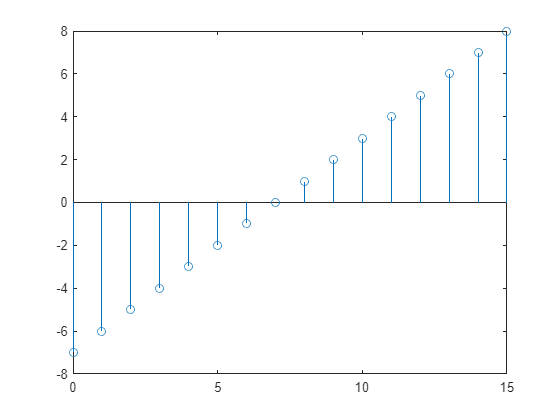

B = 16;
luti = 0:B-1;
luto = luti - B/2 + 1;
stem(luti, luto)


differC = zeros(1, length(im));

for i = 1:length(im)
    differC(i) = luto(differB(i))+1;
end

differC

differC =     -4    -3     0     1     6     6    -4    -6


differC + im

ans =     -3     1     5    12    19     8     0    -1


normalizedData = normalize(differC,"range",[0,B-1])

normalizedData =     2.5000    3.7500    7.5000    8.7500   15.0000   15.0000    2.5000         0


round(normalizedData)

ans =      3     4     8     9    15    15     3     0
